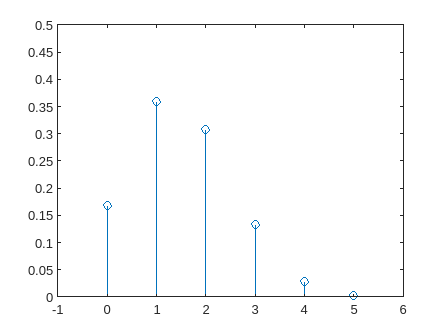

Sx=0:5;
N=1e6;

defeito=rand(5,N)<0.3;

defeito0=sum(sum(defeito) == 0);
defeito1=sum(sum(defeito) == 1);
defeito2=sum(sum(defeito) == 2);
defeito3=sum(sum(defeito) == 3);
defeito4=sum(sum(defeito) == 4);
defeito5=sum(sum(defeito) == 5);

prob0=defeito0/N;
prob1=defeito1/N;
prob2=defeito2/N;
prob3=defeito3/N;
prob4=defeito4/N;
prob5=defeito5/N;

probs = [prob0 prob1 prob2 prob3 prob4 prob5];

stem(Sx,probs)
axis([-1 6 0 0.5])

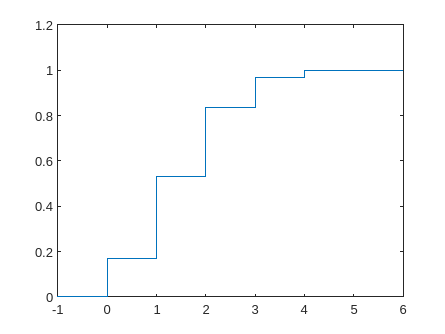


Sx=0:5;
N=1e6;

defeito=rand(5,N)<0.3;

defeito0=sum(sum(defeito) == 0);
defeito1=sum(sum(defeito) == 1);
defeito2=sum(sum(defeito) == 2);
defeito3=sum(sum(defeito) == 3);
defeito4=sum(sum(defeito) == 4);
defeito5=sum(sum(defeito) == 5);

prob0=defeito0/N;
prob1=defeito1/N;
prob2=defeito2/N;
prob3=defeito3/N;
prob4=defeito4/N;
prob5=defeito5/N;

probs = [prob0 prob1 prob2 prob3 prob4 prob5];

probs1=cumsum(probs);
stairs([-1 Sx 6],[0 probs1 1])
axis([-1 6 0 1.2])

Sx=0:5;
N=1e6;

defeito=rand(5,N)<0.3;

defeitomax2=sum(sum(defeito) <= 2);
pmax2 = defeitomax2/N

pmax2 = 0.8367

prob_teorica0 = prob_teorica(0,5,0.3);
prob_teorica1 = prob_teorica(1,5,0.3);
prob_teorica2 = prob_teorica(2,5,0.3);
prob_teorica3 = prob_teorica(3,5,0.3);
prob_teorica4 = prob_teorica(4,5,0.3);
prob_teorica5 = prob_teorica(5,5,0.3);

probTeo1=[prob_teorica0 prob_teorica1 prob_teorica2 prob_teorica3 prob_teorica4 prob_teorica5];
probTeoAcumulada= cumsum( probTeo1)

probTeoAcumulada =     0.1681    0.5282    0.8369    0.9692    0.9976    1.0000


prob_teorica0 = prob_teorica(0,5,0.3);
prob_teorica1 = prob_teorica(1,5,0.3);
prob_teorica2 = prob_teorica(2,5,0.3);

probTeoMax2 = prob_teorica0 + prob_teorica1 + prob_teorica2

probTeoMax2 = 0.8369